**All credit goes to Ali Heydari (SMU)**

This script solves the ADP problem for optimal switching between subsystems.  It can obviously be modified to handle the standard DP problem.

The control problem is a two-tank experiment where the main valve has three possible positions:  fully open, half open, and closed.  This is an example of a hybrid system, with the continuous dynamics under the control of a discrete input.

## Optimal switching control of subsystems with autonomous dynamics

First, set up the problem.

clc; clear;
dt = 0.025; %Sampling time of the discrete system
tf = 5; %The simulation will be performed from t=0 to this value
N = tf/dt; %Number of steps during each simulation 

Below are the tank dynamics.  The dynamics are essentially the same, but with different gains on the control at each step.  Playing with the values for $\alpha$can change the dynamics.  Note the nasty nonlinearities!

u_max = 1;
alpha1 = 1; alpha2 = 1;
f1 = @(x) [-alpha1*sqrt(x(1))+0*u_max
            alpha1*sqrt(x(1))-alpha2*sqrt(x(2))];
        
f2 = @(x) [-alpha1*sqrt(x(1))+0.5*u_max
            alpha1*sqrt(x(1))-alpha2*sqrt(x(2))];
        
f3 = @(x) [-alpha1*sqrt(x(1))+u_max
            alpha1*sqrt(x(1))-alpha2*sqrt(x(2))];


Start as some initial state and generate the basis functions that will be used to fit the cost-to-go function.  Here he is just using a polynomial for the fit.

n = 2;
X_k =  (rand(n,1)*2-1); %Initial states selection
        
% Up to the fourth order
phi = @(X) [1; X(1); X(2);
                X(1)^2; X(2)^2; X(1)*X(2); 
                X(1)^3; X(2)^3; X(1)^2*X(2); X(1)*X(2)^2
                X(1)^4; X(2)^4; X(1)^3*X(2); X(1)*X(2)^3; X(1)^2*X(2)^2
                X(1)^5; X(2)^5; X(1)^4*X(2); X(1)*X(2)^4; X(1)^3*X(2)^2; X(1)^2*X(2)^3
               ];

## Offline training

This is where we fit the function to the cost-to-go.  Basically, start with a bunch of random states at each time, and learn the function for that step.

FinalW gives the coefficients of the fit at each value of k.  Here I am running 100 experiments at each step.

FinalW = zeros(length(phi(X_k)),N);
NoOfEquations = 100;

Now setup the reference position and the cost parameters.  Qdis is the running cost (i.e. $x^TQx$) and S is the final cost.

xr = [0, 0.5]'; % The reference for 
Q = diag([0,20]);  %Weight only the 2nd state.
QDis = dt*Q;
S = zeros(2,2);  %Setting to zero

Here he's setting up a least squares problem for curve fitting.

RHS_J = zeros(NoOfEquations,1);
LHS_J = zeros(NoOfEquations,length(phi(X_k)));

Training Process

Now the training begins!  

diverged = 0;
for t = 0:N-1  %Step through each value 
    k = N - t; %Changing from N to 1
    W(:,k,1) = FinalW(:,k);
    if diverged == 0
        for i=1:NoOfEquations
            X_k(1) =  rand; % Random state selection for training
            X_k(2) =  0.75*rand;
            if k == N %If at the terminal step
                J_k_t = 0.5*(X_k-xr)'*S*(X_k-xr);  %This is the terminal cost
                RHS_J(i,:) = J_k_t;
                LHS_J(i,:) = phi(X_k)';
            else  %Not at the terminal step
                temp_x1 = X_k + dt*f1(X_k);  %Numerical integration to find the next step for each model
                temp_x2 = X_k + dt*f2(X_k);
                temp_x3 = X_k + dt*f3(X_k);
                
                

Here the cost is projected for the next step in given each of the possible new dynamics.  By now we have already learning FinalW at N at the very least.

                
                temp_j1 = FinalW(:,k+1)'*phi(temp_x1);
                temp_j2 = FinalW(:,k+1)'*phi(temp_x2);
                temp_j3 = FinalW(:,k+1)'*phi(temp_x3);
  

Pick the control (subsystem) that will minimize the projected cost.

                
                if temp_j1 <= min(temp_j2,temp_j3)
                    X_k_plus_1 = temp_x1;
                elseif  temp_j2 <= temp_j3
                    X_k_plus_1 = temp_x2;
                else
                    X_k_plus_1 = temp_x3;
                end
                

Now simply compute the cost to go.

                J_k_plus_1 = FinalW(:,k+1)'*phi(X_k_plus_1);
                J_k_t = 0.5*(X_k-xr)'*QDis*(X_k-xr) + J_k_plus_1;
                RHS_J(i,:) = J_k_t;
                LHS_J(i,:) = phi(X_k)';
            end
        end
        

Now he solves the least squares problem to get the optimal curve fit.  The last check is to make sure the learning is not blowing up.

        if det(LHS_J'*LHS_J)==0
            fprintf('det phi = 0\n');
            break;
        end;
        FinalW(:,k) = (LHS_J'*LHS_J)^-1*LHS_J'*RHS_J;
        
        if isnan(FinalW(:,k))
            fprintf('Training W is diverging...\n');
            diverged = 1;
            break;
        end;
    end;
end

The graph below shows the elements of the curve fit as a function of the iteration. 

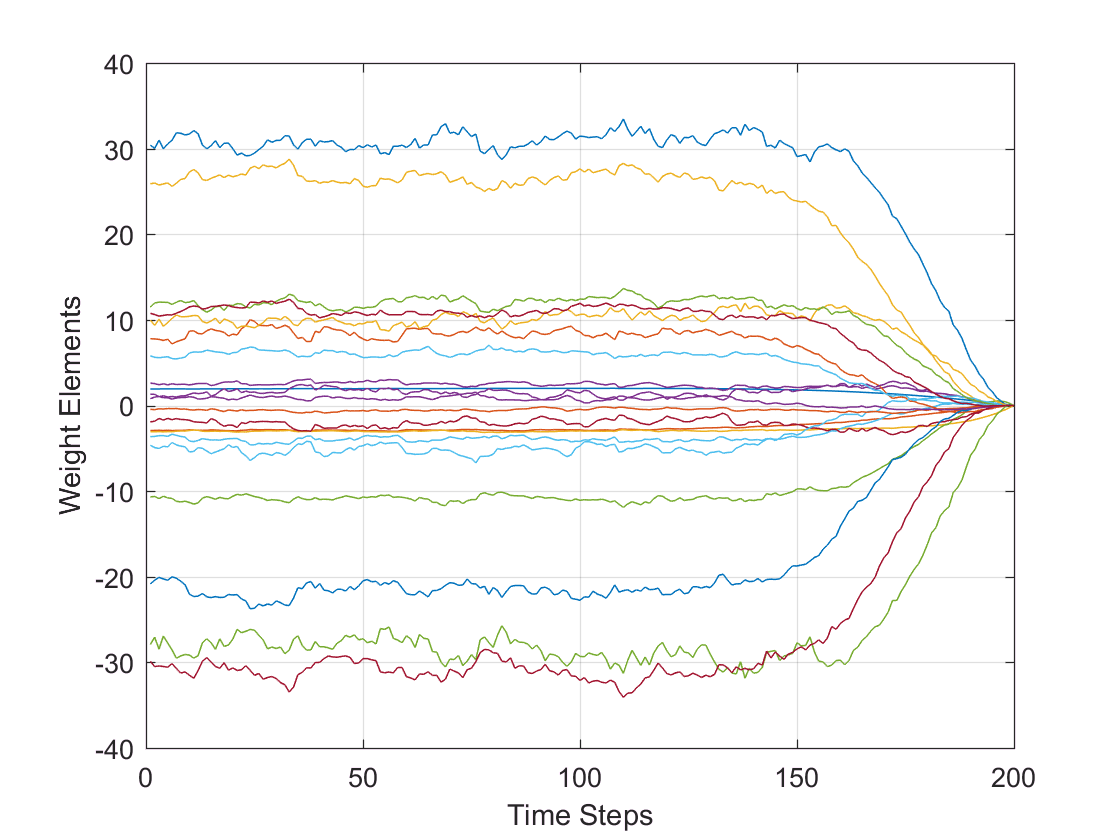

plot([1:N], FinalW(:,1:N))
xlabel('Time Steps'); ylabel('Weight Elements'); grid on

## Online control

Setup the starting point.

U1=zeros(1,N);
X1=zeros(n,N);
N0 = 1;
X1(:,N0) = [1;1]; % Initial condition
Cost1=0;

r = 0.00; %Threshold - make this non-zero to penalize switching between subsystems

for i = N0:N-1

## Finite Horizon Solution

At each step, consider the three possible types of dynamics along with the three possible cost-to-go values.

    temp_x1 = X1(:,i) + dt*f1(X1(:,i));
    temp_x2 = X1(:,i) + dt*f2(X1(:,i));
    temp_x3 = X1(:,i) + dt*f3(X1(:,i));

    temp_j1 = FinalW(:,i+1)'*phi(temp_x1);
    temp_j2 = FinalW(:,i+1)'*phi(temp_x2);
    temp_j3 = FinalW(:,i+1)'*phi(temp_x3);

Here he just computes the control that gives the lowest cost along with the next state.

        if temp_j1 <= min(temp_j2,temp_j3)
            U1(i) = 1;
            X1(:,i+1) = X1(:,i) + dt*f1(X1(:,i));
        elseif  temp_j2 <= temp_j3
            U1(i) = 2;
            X1(:,i+1) = X1(:,i) + dt*f2(X1(:,i));
        else
            U1(i) = 3;
            X1(:,i+1) = X1(:,i) + dt*f3(X1(:,i));
        end
    Cost1 = Cost1 + 1/2*((X1(:,i)-xr)'*Q*(X1(:,i)-xr))*dt;  %Keep a running cost
end
    Cost1 = Cost1 + 1/2*((X1(:,end)-xr)'*S*(X1(:,end)-xr))  %Add the terminal cost

Cost1 = 2.1164

Now let's look at the performance of the algorithm

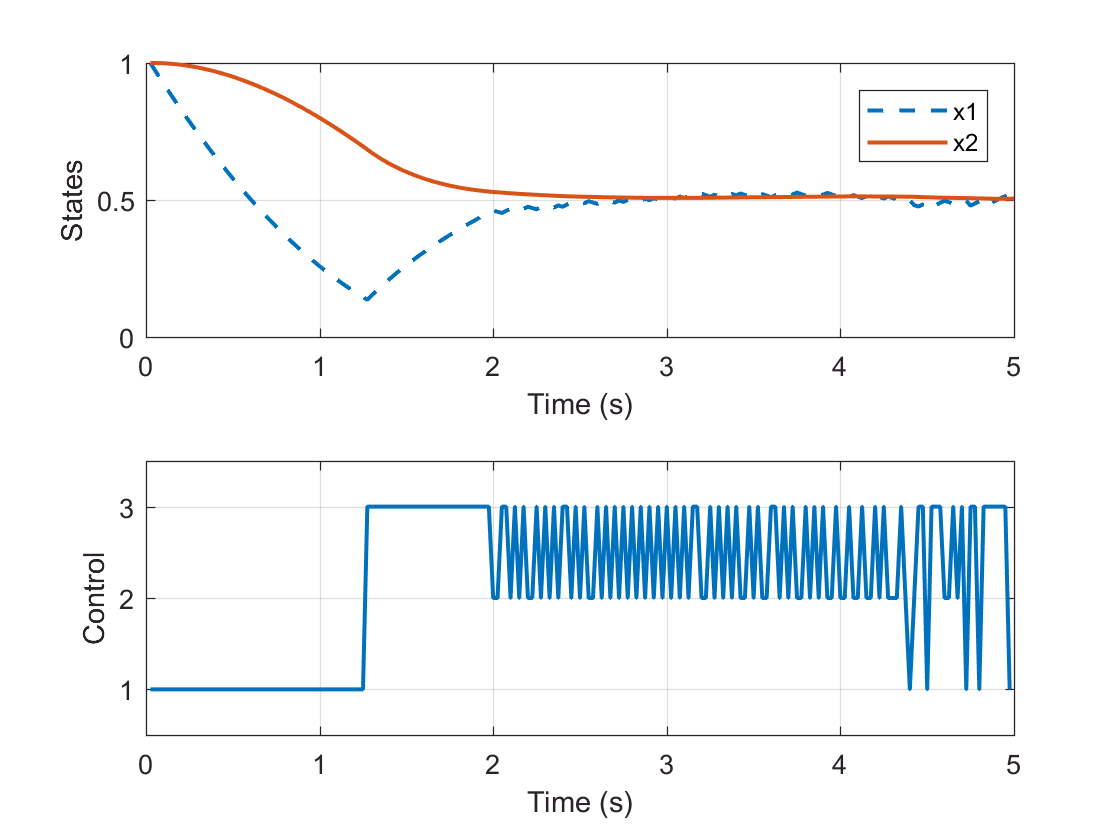

subplot(2,1,1)
plot([1:N-N0+1]*dt, X1(1,N0:N),'--', [1:N-N0+1]*dt, X1(2,N0:N), 'linewidth',1.5);
xlabel('Time (s)'); ylabel('States'); grid on
legend('x1','x2')

subplot(2,1,2)
plot([1:N-N0]*dt, U1(N0:N-1), 'linewidth',1.5);
ylim([0.5,3.5])
xlabel('Time (s)');  ylabel('Control'); grid on